# Pb1 - Facultativa

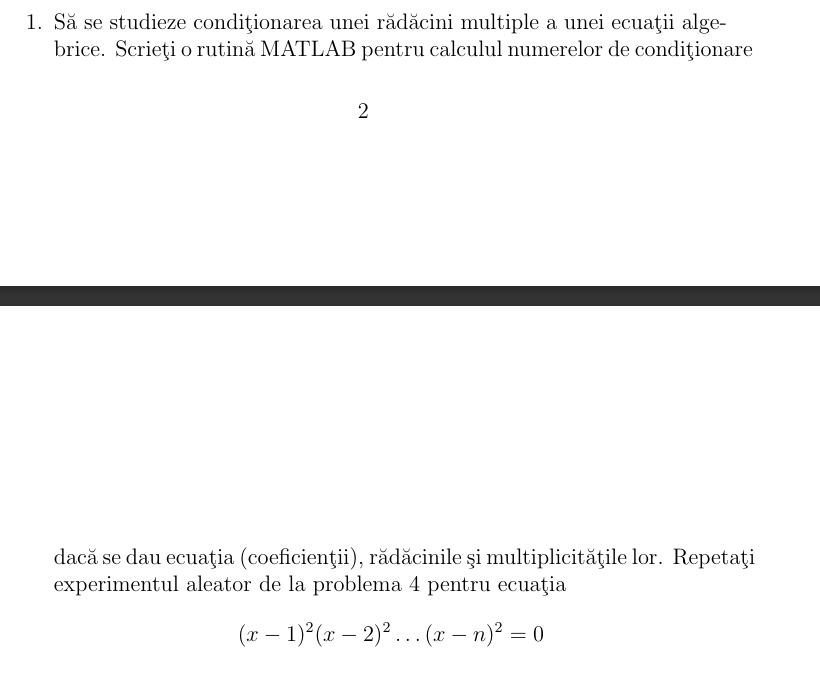

n = 20; 

radacini = repelem(1:n, 2);  % [1 1 2 2 3 3 ... n n]
p = poly(radacini);
roots_orig = roots(p)

roots_orig =   25.8221 + 0.0000i
  25.1646 + 3.1954i
  25.1646 - 3.1954i
  23.3470 + 5.8827i
  23.3470 - 5.8827i
  20.7573 + 7.7149i
  20.7573 - 7.7149i
  17.8729 + 8.5795i
  17.8729 - 8.5795i
  18.5643 + 0.0000i



% Perturbare normala
perturb_normal = randn(size(p)) * 1e-10;
p_pert_normal = p + perturb_normal;
roots_pert_normal = roots(p_pert_normal)

roots_pert_normal =   26.0124 + 1.6926i
  26.0124 - 1.6926i
  24.7325 + 4.3147i
  24.7325 - 4.3147i
  23.0188 + 6.7039i
  23.0188 - 6.7039i
  20.3034 + 8.4149i
  20.3034 - 8.4149i
  17.3693 + 9.0196i
  17.3693 - 9.0196i



% Perturbare uniforma
perturb_uniform = (rand(size(p)) - 0.5) * 2 * 1e-10;
p_pert_uniform = p + perturb_uniform;
roots_pert_uniform = roots(p_pert_uniform)

roots_pert_uniform =   26.1891 + 2.1580i
  26.1891 - 2.1580i
  24.0519 + 5.5248i
  24.0519 - 5.5248i
  21.4166 + 7.2150i
  21.4166 - 7.2150i
  18.9256 + 8.3844i
  18.9256 - 8.3844i
  16.1045 + 8.8836i
  16.1045 - 8.8836i


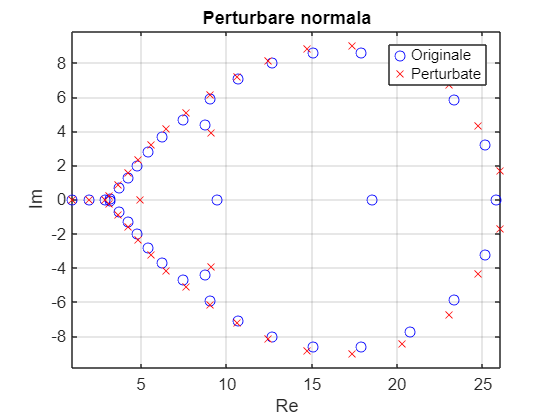




figure;
plot(real(roots_orig), imag(roots_orig), 'bo'); hold on;
plot(real(roots_pert_normal), imag(roots_pert_normal), 'rx');
title('Perturbare normala');
xlabel('Re'); ylabel('Im');
axis equal; grid on; legend('Originale','Perturbate');

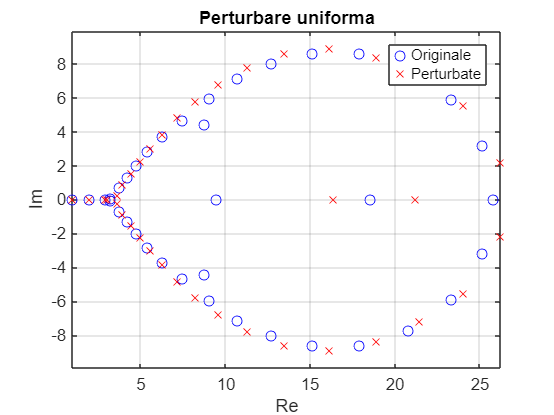


figure;
plot(real(roots_orig), imag(roots_orig), 'bo'); hold on;
plot(real(roots_pert_uniform), imag(roots_pert_uniform), 'rx');
title('Perturbare uniforma');
xlabel('Re'); ylabel('Im');
axis equal; grid on; legend('Originale','Perturbate');





r1 = sort(roots_orig);
r2_normal = sort(roots_pert_normal);
r2_uniform = sort(roots_pert_uniform);

eroare_normal = norm(r2_normal - r1) / norm(r1);
eroare_uniform = norm(r2_uniform - r1) / norm(r1);

fprintf("Eroare relativa (normala):  %.3e\n", eroare_normal);

Eroare relativa (normala):  5.006e-01


fprintf("Eroare relativa (uniforma): %.3e\n", eroare_uniform);

Eroare relativa (uniforma): 4.554e-01



if eroare_normal > eroare_uniform
    fprintf("Perturbarea normala are efect MAI MARE.\n");
else
    fprintf("Perturbarea uniforma are efect MAI MARE.\n");
end

Perturbarea normala are efect MAI MARE.
